加载数据文件

load bank.mat

将数据进行处理

先将所有变量名提出

names = bank.Properties.VariableNames;

然后得到所有变量中为字符串的变量的位置

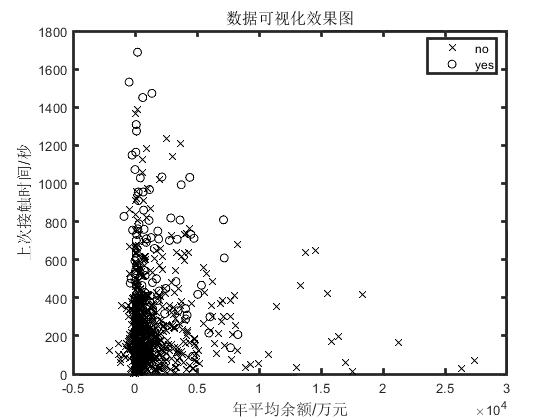

category = varfun(@iscellstr, bank, 'Output', 'uniform');
for i = find(category) % find返回非零元素索引向量
    bank.(names{i}) = categorical(bank.(names{i}));
end
catPred = category(1:end - 1);
rng('default');
figure(1)
gscatter(bank.balance, bank.duration, bank.y, 'kk', 'xo')
xlabel('年平均余额/万元', 'fontsize', 12)
ylabel('上次接触时间/秒', 'fontsize', 12)
title('数据可视化效果图', 'fontsize', 12)
set(gca, 'linewidth', 2);

计算统计结果

X = table2array(varfun(@double, bank(:, 1:end - 1)));
Y = bank.y;
disp('数据中的Yes&No的统计结果：')

数据中的Yes&No的统计结果：


tabulate(Y)

  Value    Count   Percent
     no      888     88.80%
    yes      112     11.20%


XNum = [X(:, ~catPred) dummyvar(X(:, catPred))];
YNum = double(Y) - 1;

训练准备

cv = cvpartition(height(bank), 'HoldOut', 0.40);

训练集

Xtrain = X(training(cv), :);
Ytrain = Y(training(cv), :);
XtrainNum = XNum(training(cv), :);
YtrainNum = YNum(training(cv), :);

测试集

Xtest = X(test(cv), :);
Ytest = Y(test(cv), :);
XtestNum = XNum(test(cv), :);
YtestNum = YNum(test(cv), :);
disp('训练集：')

训练集：


tabulate(Ytrain)

  Value    Count   Percent
     no      528     88.00%
    yes       72     12.00%


disp('测试集：')

测试集：


tabulate(Ytest)

  Value    Count   Percent
     no      360     90.00%
    yes       40     10.00%


准备开始训练

knn = ClassificationKNN.fit(Xtrain, Ytrain, 'Distance', 'seuclidean', 'NumNeighbors', 5);
[Y_knn, Yscore_knn] = knn.predict(Xtest);
disp('最近邻方法分类结果')

最近邻方法分类结果


C_knn = confusionmat(Ytest, Y_knn)

C_knn =    352     8
    28    12
